% Task 1: For loop use

% define variables
true_pi = pi;  
N_values = [1000, 10000, 100000, 500000, 1000000];  % Different numbers of random points
computed_pi = zeros(size(N_values));  % Array to store computed Pi values
deviation = zeros(size(N_values));  % Array to store deviations from true Pi
execution_times = zeros(size(N_values));  % Array for execution times

% For loop over each number of points in N_values
for j = 1:length(N_values)
    N = N_values(j);  
    inside_circle = 0;  

    % measuring execution time
    tic;
    
    % Generate random points and check if they are inside the quarter circle
    for i = 1:N
        x = rand;
        y = rand;
        if x^2 + y^2 <= 1
            inside_circle = inside_circle + 1;
        end
    end
    
    % Estimate Pi
    computed_pi(j) = 4 * inside_circle / N;
    
    % deviation from the true Pi value
    deviation(j) = abs(computed_pi(j) - true_pi);
    
    % Record execution time
    execution_times(j) = toc;
    
    % Print details for each iteration
    fprintf('N = %d, Computed Pi = %.10f, Deviation = %.10f, Execution Time = %.5f seconds\n', ...
            N, computed_pi(j), deviation(j), execution_times(j));
end

N = 1000, Computed Pi = 3.1120000000, Deviation = 0.0295926536, Execution Time = 0.01176 seconds
N = 10000, Computed Pi = 3.1304000000, Deviation = 0.0111926536, Execution Time = 0.00135 seconds
N = 100000, Computed Pi = 3.1518400000, Deviation = 0.0102473464, Execution Time = 0.00647 seconds
N = 500000, Computed Pi = 3.1448080000, Deviation = 0.0032153464, Execution Time = 0.03239 seconds
N = 1000000, Computed Pi = 3.1389120000, Deviation = 0.0026806536, Execution Time = 0.06608 seconds


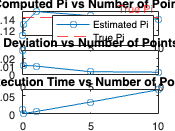


% Plot the computed value of Pi as the number of points increases
figure;
subplot(3,1,1);
plot(N_values, computed_pi, '-o');
hold on;
yline(true_pi, '--r', 'True Pi');
xlabel('Number of Points');
ylabel('Computed Pi');
title('Computed Pi vs Number of Points');
legend('Estimated Pi', 'True Pi');
hold off;

% Plot the deviation from true Pi as the number of points increases
subplot(3,1,2);
plot(N_values, deviation, '-o');
xlabel('Number of Points');
ylabel('Deviation from True Pi');
title('Deviation vs Number of Points');

% Plot the execution time as the number of points increases
subplot(3,1,3);
plot(N_values, execution_times, '-o');
xlabel('Number of Points');
ylabel('Execution Time (seconds)');
title('Execution Time vs Number of Points');

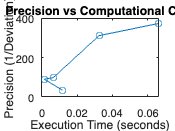


% Create a plot comparing precision (1/Deviation) to computational cost (Execution Time)
figure;
plot(execution_times, 1./deviation, '-o');
xlabel('Execution Time (seconds)');
ylabel('Precision (1/Deviation)');
title('Precision vs Computational Cost');